# Unit Root Testing

## **Exercise** 62

The first part of Exercise 61 is to download the data on AAA and BAA yields from Moody’s  from FRED. Let's use the **fetch** function discussed in the previous classes to do this.

clear all
clc
% Downloading the AAA yields data: 
aaa = fetch(fred(), 'AAA')

aaa = struct with fields:
                 Title: ' Moody's Seasoned Aaa Corporate Bond Yield'
              SeriesID: ' AAA'
                Source: ' Moody’s'
               Release: ' Moody's Daily Corporate Bond Yield Averages (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1919-01-01 to 2020-01-01'
           LastUpdated: ' 2020-02-03 10:16 AM CST'
                 Notes: ' These instruments are based on bonds with maturities 20 years and above.   © 2017, Moody’s Corporation, Moody’s Investors Service, Inc., Moody’s Analytics, Inc. and/or their licensors and affiliates (collectively, “Moody’s”). All rights reserved. Moody’s ratings and other information (“Moody’s Information”) are proprietary to Moody’s and/or its licensors and are protected by copyright and other intellectual property laws. Moody’s Information is licensed to Client by Moody’s. MOODY’S INFORMAT

% Downloading the BAA yields data:
baa = fetch(fred(), 'BAA')

baa = struct with fields:
                 Title: ' Moody's Seasoned Baa Corporate Bond Yield'
              SeriesID: ' BAA'
                Source: ' Moody’s'
               Release: ' Moody's Daily Corporate Bond Yield Averages (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Percent'
             DateRange: ' 1919-01-01 to 2020-01-01'
           LastUpdated: ' 2020-02-03 10:16 AM CST'
                 Notes: ' These instruments are based on bonds with maturities 20 years and above.   © 2017, Moody’s Corporation, Moody’s Investors Service, Inc., Moody’s Analytics, Inc. and/or their licensors and affiliates (collectively, “Moody’s”). All rights reserved. Moody’s ratings and other information (“Moody’s Information”) are proprietary to Moody’s and/or its licensors and are protected by copyright and other intellectual property laws. Moody’s Information is licensed to Client by Moody’s. MOODY’S INFORMAT

Let's begin by plotting these two yields with different risk profiles.

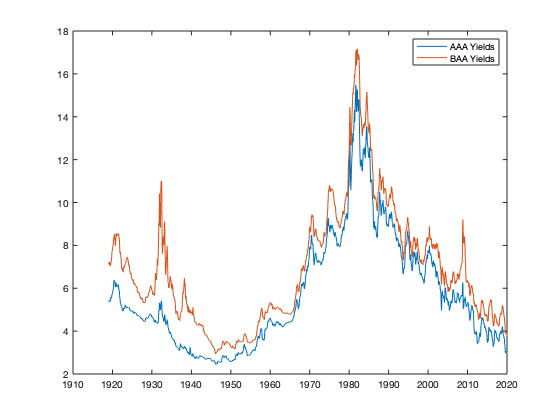

% Getting the vector of dates
dates = aaa.Data(:,1);
% Plotting:
plot(dates,[aaa.Data(:,2), baa.Data(:,2)])
legend('AAA Yields', 'BAA Yields')
datetick('x')

The plot makes sense. We expect the BAA yields to be higher than the AAA yields, given that the former is made of riskier bonds than the latter. The series go way back to the 20s and show us that the financialization of the economy has helped to reduce the difference in financing costs for lower graded firms. 

But let's turn to what matters. As the term premium was the difference between the 10-year bond yield and the 1-year bond yield, the default premium is defined as the difference between the BAA yield and the AAA yield. The logic behind it is very straightforward. Riskier companies should pay higher interest rates on their bonds. This "premium" for riskier firms is what we are measuring by the default premium. 

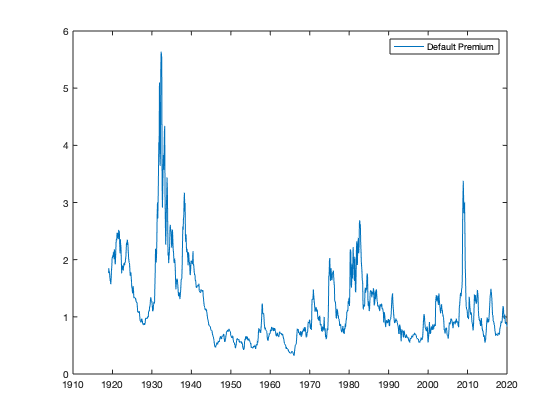

% Calculating the default premium:
def = baa.Data(:,2)-aaa.Data(:,2);
% Plotting the default premium:
plot(dates,def)
legend('Default Premium')
datetick('x')

As we can see, different to the term premium, the default premium has never been negative. Again, this makes sense. Given that the only difference between AAA yields and BAA yields is the risk profile, BAA bonds should always pay a premium. Since, *ceteris paribus*, the higher the risk of a bond, the higher should be its yield. 

## **Exercise** 61.a 

Turning to the question itself, it is hard to tell if the default premium is a unit root simply by looking at the figure above. The series seems fairly well behaved during most of the time. Nevertheless, there are some significant jumps during what looks like financial crises. But this is not a problem! As you have seen with Matthias, there are formal tests we can perform in order to check if a series possesses a unit root. 

One more time, the MFE Toolbox comes to save the day. We can use it to perform the Dickey-Fuller and Augmented Dickey Fuller tests. Let's take a look into Kevin's notes to remember what these tests do.

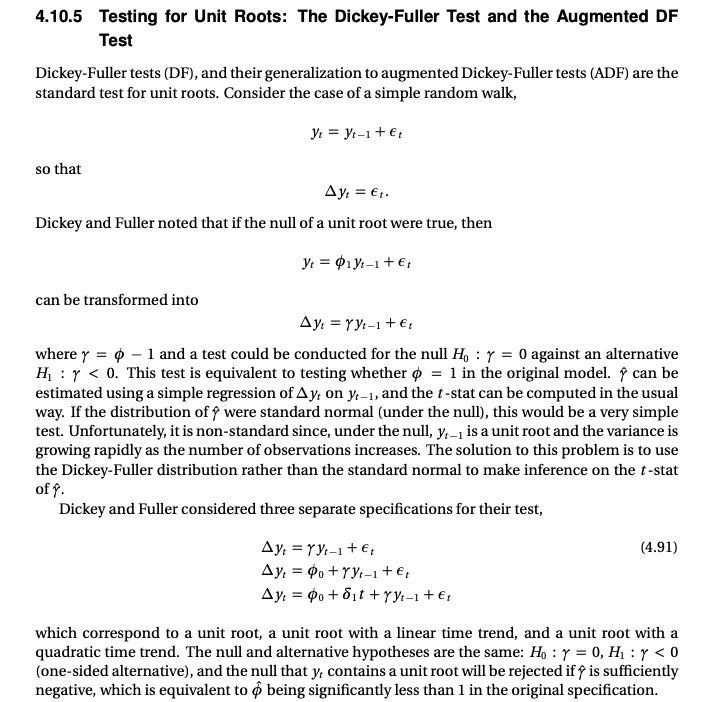

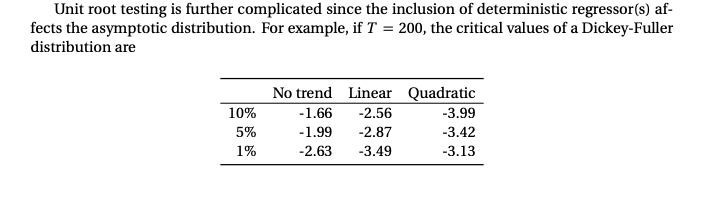

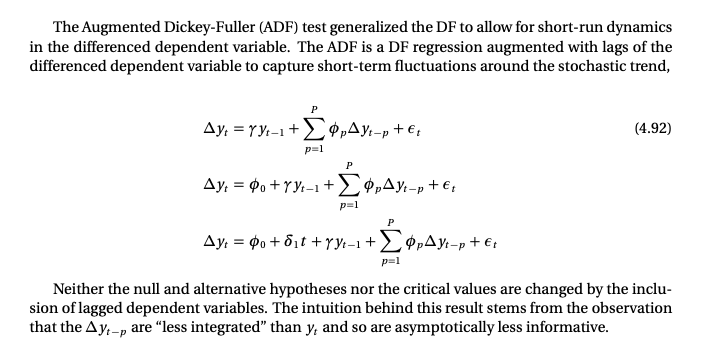

Now that we have recalled how the test works. Let's check the function `augdfautolag` in the MFE Toolbox:

help augdfautolag

  Dickey-Fuller and Augmented Dickey Fuller with automatic lag selection
 
  USAGE:
   [ADFSTAT,PVAL,CRITVAL] = augdfautolag(Y,P,LAGS,IC)
   [ADFSTAT,PVAL,CRITVAL,RESID,LAGS] = augdfautolag(Y,P,LAGS,IC)
 
  INPUTS:
   Y         - A T by 1 vector of data
   P         - Order of the polynomial of include in the ADF regression:
                 0 : No deterministic terms
                 1 : Constant
                 2 : Time Trend
                 3 : Constant, DGP assumed to have a time trend
   MAXLAGS   - The maximum number of lags to include in the ADF test
   IC        - [OPTIONAL] String, either 'AIC' (default) or 'BIC' to choose the criteria to select
                 the model
 
  OUTPUTS:
   ADFSTAT   - Dickey-Fuller statistic
   PVAL      - Probability the series is a unit root
   CRITVALS  - A 6 by 1 vector with the [.01 .05 .1 .9 .95 .99] values from the DF distribution
   LAGS      - The selected number of lags
   IC        - The value at all lags of the selected IC
 
  COMM

We can begin our unit root tests by the most restrictive test. Hence, we do an ADF with no trend or constant. Notice that one important input of the function `augdfautolag` is the maximum number of lags to be considered in the test. This input (`LAGS`) is not necessarily the number of lags that will be used in the test. The `augdfautolag` chooses the appropriate number of lags to be included in the ADF test according to AIC (standard) or BIC (if requested) using the input `LAGS` as the maximum number of lags to be considered.

% Doing the test:
[ts, pv] = augdfautolag(def,0,20);
disp('Probability of unit root:')

Probability of unit root:


disp(pv)

     0.041009



By looking at the p-value, we see that the null of the default premium presenting a unit root is marginally rejected. To be sure, let's expand the test by allowing for a constant in the ADF difference equation. That is, by allowing for a linear time trend in the default premium.

% Doing the test:
[ts, pv] = augdfautolag(def,1,20);
disp('Probability of unit root:')

Probability of unit root:


disp(pv)

    0.0036907



When we allow for a constant in the ADF equation, we can strongly reject the null of the default premium having a unit root. 

## **Exercise** 63.a.

This exercise asks us to perform the same analysis we did for the default premium to the UK's Consumer Price Index (CPI). Although the question requested us to collect the CPI data from ONS, I'll use the OECD series available at the FRED so we can use the `fetch` function to import the data automatically using MATLAB. 

clear all
clc
% Downloading the CPI data: 
cpi = fetch(fred(), 'GBRCPIALLMINMEI')

cpi = struct with fields:
                 Title: ' Consumer Price Index of All Items in the United Kingdom'
              SeriesID: ' GBRCPIALLMINMEI'
                Source: ' Organization for Economic Co-operation and Development'
               Release: ' Main Economic Indicators (Not a Press Release)'
    SeasonalAdjustment: ' Not Seasonally Adjusted'
             Frequency: ' Monthly'
                 Units: ' Index 2015=100'
             DateRange: ' 1960-01-01 to 2019-11-01'
           LastUpdated: ' 2020-01-29 7:24 AM CST'
                 Notes: ' Copyright, 2016, OECD. Reprinted with permission.  All OECD data should be cited as follows: OECD (2010), "Main Economic Indicators - complete database", Main Economic Indicators (database),http://dx.doi.org/10.1787/data-00052-en (Accessed on date)'
                  Data: [719×2 double]


Again, let's begin by plotting this CPI series.

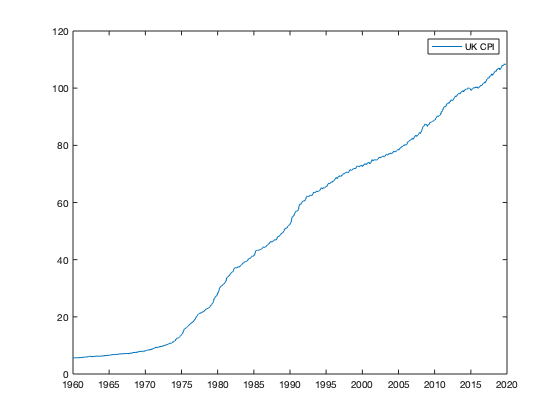

% Getting the vector of dates
dates = cpi.Data(:,1);
cpi_uk = cpi.Data(:,2);
% Plotting:
plot(dates,cpi_uk)
legend('UK CPI')
datetick('x')

Now this is how a series with a unit root looks like! We can see that the CPI series is very explosive and it surely doesn’t look to be well behaved within a range. But to be sure, let's conduce the Dickey Fuller test for unit root. Because by looking at the figure above we can be fairly certain that the CPI process has a unit root, we can already start with the most flexible version of the Dickey Fuller test (that allows for constant and trend in the ADF difference equation), rather than starting with the most restrictive one. 

% Doing the test:
[ts, pv] = augdfautolag(cpi_uk,3,20);
disp('Probability of unit root:')

Probability of unit root:


disp(pv)

      0.59373



As expected, we cannot reject the null of the CPI having a unit root even with the most flexible version of the Dickey Fuller test. 

## **Exercise** 63.b.

So what do we do next? As you know, when we find that a process has a unit root, the usual solution is to take the difference. The hope is that the initial process was I(1) (integrated of order one) and therefore, by taking differences of this process, we are left with an I(0) (stationary) process. 

Here, rather than being asked to analyse the difference of CPI per se, the questions asks us to take a look at inflation rate; which is just the percentage change on CPI. In the case of the CPI, this difference of the process is also a lot more meaningful that the process itself and is what we are generally interested in. So let's calculate and take a look at inflation.

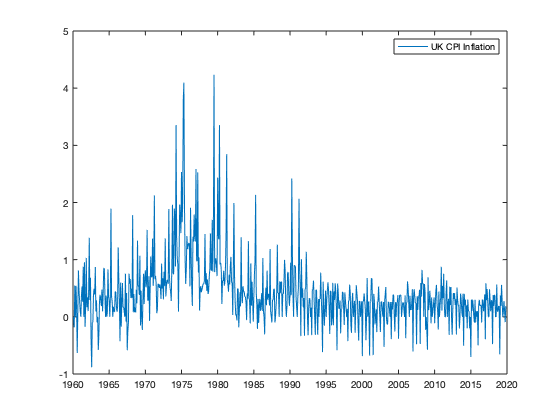

% Calculating inflation:
inflation = diff(log(cpi_uk))*100;

% Plotting:
plot(dates(2:end),inflation)
legend('UK CPI Inflation')
datetick('x')

This looks a lot more stable than CPI! Analysing the inflation series also allows us to see in which periods we had the largest increases in prices. Obviously, monthly inflation is a lot noisier than yearly inflation and hence we can't see much more than the fact that inflation was higher in the 70s and 80s than it is nowadays. 

Finally, let's test the inflation series for a unit root. Starting with an ADF test with no constant or trend:

% Doing the test:
[ts, pv] = augdfautolag(inflation,0,20);
disp('Probability of unit root:')

Probability of unit root:


disp(pv)

     0.070435



As the next step, let's expand the test by allowing for a constant and trend in the ADF difference equation (you can try different ADF functional forms in between). 

% Doing the test:
[ts, pv] = augdfautolag(inflation,3,20);
disp('Probability of unit root:')

Probability of unit root:


disp(pv)

    0.0039328



By allowing for the constant and trend in the Dickey Fuller difference equation, we are able to reject the null of the inflation process having a unit root.